# TEMA 3. ÀLGEBRA LINEAL NUMÈRICA

## Valors i vectors propis d'una matriu

### Idea: Av tendeix al vector propi de valor propi màxim

clearvars
A = [1.8,0.8; 0.2,1.2]

A =     1.8000    0.8000
    0.2000    1.2000


[V,S] = eig(A);

% Mòdul màxim
%v = V(:,1),  y = [-0.5;1],  B = A;

% Mòdul mínim
% v = V(:,2), y = -[0.5;1], B = inv(A);

% llista = [y/norm(y)];
% for k = 2:5; %8    
%     y= B*y;
%     llista = [llista,k*y/norm(y)];
% end
% % Gràfica
% U = llista(1,:); V = llista(2,:);
% n=k+1;
% compass(n*v(1),n*v(2),'r')
% hold on
% compass(U,V)
% hold off

#### Fites, cercles de Gershgoring

clf
fites = [norm(A),norm(A,1),norm(A,'inf'),norm(A,'fro')]  % vap <=||A||

fites =     2.1128    2.0000    2.6000    2.3152


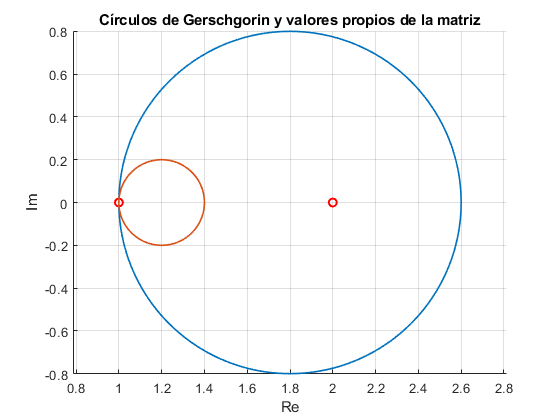

C =     1.8000         0    0.8000
    1.2000         0    0.2000


C = Gershgoring(A)   % |z-a(i,i)| <= sum(|a(i,:)|)-|a(i,i)|

function C = Gershgoring(A)
%% Se dibujan los círculos de Gerschgorin de la matriz A.
    [m n] = size(A);
    d = diag(A); cx = real(d); cy = imag(d);
    B = A - diag(d);
    r = sum(abs(B')); % Suma filas de A sin diagonal
    C = [cx cy r(:)];
    t = 0:pi/100:2*pi; c = cos(t); s = sin(t);
    [v d] = eig(A); % eig calcula los valores propios de A
    d = diag(d); % En d valores propios
    u1 = real(d); v1 = imag(d);
    hold on, grid on, axis equal
    xlabel('Re'), ylabel('Im')
    h1_line = plot(u1,v1,'or');
    set(h1_line,'LineWidth',1.5)
    for i=1:n % Se dibujan los círculos de Gerscgorin
        x = zeros(1,length(t)); y = zeros(1,length(t));
        x = cx(i)+r(i)*c; y = cy(i)+r(i)*s;
        h2_line = plot(x,y);
        set(h2_line,'LineWidth',1.2)
    end
    hold off
    title('Círculos de Gerschgorin y valores propios de la matriz')
end
%------------------------------------------------------------------